# 2.3 频域分析：频率响应、DTFT 与对称性、z 变换收敛域、s–z 映射

在 MATLAB 编辑器中打开，点击“运行”；或逐节运行。仅使用基础 MATLAB。

clearvars;
LIVE = strcmp(getenv('DSP_LIVE'), '1');
if LIVE, newpanel = @(varargin) figure('Color','w','Position',[80 80 640 420]); else, newpanel = @(varargin) nexttile(varargin{:}); end
if LIVE, set(groot, 'defaultLegendLocation', 'southoutside'); else, set(groot, 'defaultLegendLocation', 'best'); end
outdir = fullfile(fileparts(mfilename('fullpath')), 'results');
if ~exist(outdir, 'dir'), mkdir(outdir); end

## 演示1：频率响应——输入 e^{jωn}，输出还是 e^{jωn}，只是乘了 H(e^{jω})（教材 2.3.1）

系统：5 点滑动平均。预测：ω=0.4π 时输出多大？

M = 5; h = ones(1, M)/M;
w = linspace(-2*pi, 2*pi, 2001);
H = @(w) sum(h.' .* exp(-1i*(0:M-1).'*w), 1);       % 按定义求和 H(e^{jω}) = Σ h(n) e^{-jωn}
wTest = [0.2 0.4 0.8]*pi; nTest = 0:59;
ampOut = zeros(size(wTest));
for k = 1:numel(wTest)
    yk = filter(h, 1, exp(1i*wTest(k)*nTest));      % 复指数输入
    ampOut(k) = abs(yk(end));                       % 稳态输出幅度
end
ampFormula = abs(H(wTest));                         % |sin(5ω/2)/(5 sin(ω/2))|

## 演示2：DTFT 及实序列的对称性（教材 2.3.2、2.3.3）

x = [1 2 3 2 1]; nx = 0:4;
X = @(w) sum(x.' .* exp(-1i*nx.'*w), 1);
Xw = X(w);
symMag = max(abs(abs(X(w)) - abs(X(-w))));          % 幅度偶对称
symPhase = max(abs(angle(X(w(abs(Xw) > 1e-6))) + angle(X(-w(abs(Xw) > 1e-6)))));   % 相位奇对称（避开零点）
symRe = max(abs(real(X(w)) - real(X(-w)))); symIm = max(abs(imag(X(w)) + imag(X(-w))));

## 演示3：z 变换与收敛域——同一个 X(z)，两种序列，靠收敛域区分（教材 2.3.4）

a = 0.8; nz = -40:40;
x1 = a.^nz .* (nz >= 0);                            % 右边序列：ROC |z| > 0.8，含单位圆 → 有 DTFT
x2 = -a.^nz .* (nz <= -1);                          % 左边序列：ROC |z| < 0.8，不含单位圆
Xz = @(z) 1 ./ (1 - a*z.^-1);                       % 两者的 X(z) 相同：1/(1−a z^{-1})
wq = linspace(-pi, pi, 801);
X1dtft = sum(x1.' .* exp(-1i*nz.'*wq), 1);          % 直接求和收敛
X1formula = Xz(exp(1i*wq));
errROC = max(abs(X1dtft - X1formula));
partialX2 = cumsum(abs(x2(end:-1:1)));              % 左边序列 Σ|x2| 随项数发散

## 演示4：拉普拉斯、傅里叶、z 之间：z = e^{sT}，虚轴绕到单位圆上（教材 2.3.5）

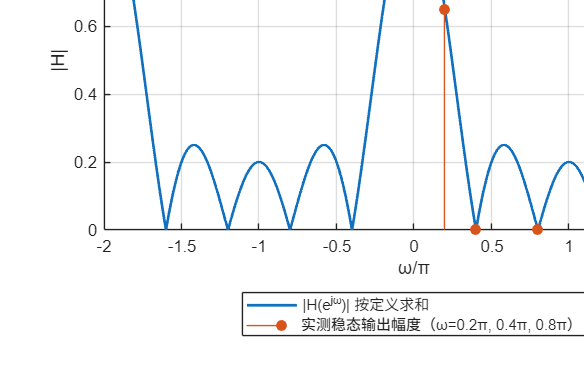

T = 1/100; Ws = 2*pi/T;
Omega = [0 Ws/8 Ws/4 Ws/2 3*Ws/4 Ws];               % s 平面虚轴上的几个点
zmap = exp(1i*Omega*T);                             % 映到 z 平面

if ~LIVE, f1 = figure('Name','01 频域分析','Color','w','Position',[60 40 1250 900]); end
if ~LIVE, tiledlayout(2,2,'TileSpacing','compact','Padding','compact'); end
newpanel(); plot(w/pi, abs(H(w)), 'LineWidth', 1.6); hold on;
stem(wTest/pi, ampOut, 'filled', 'MarkerSize', 6, 'Color', [0.85 0.33 0.1]); grid on; xlim([-2 2]);
title('① 5 点平均的 |H(e^{jω})|：以 2π 为周期；点是实际输入 e^{jωn} 测得的输出幅度'); xlabel('ω/π'); ylabel('|H|');
legend('|H(e^{jω})| 按定义求和','实测稳态输出幅度（ω=0.2π, 0.4π, 0.8π）');

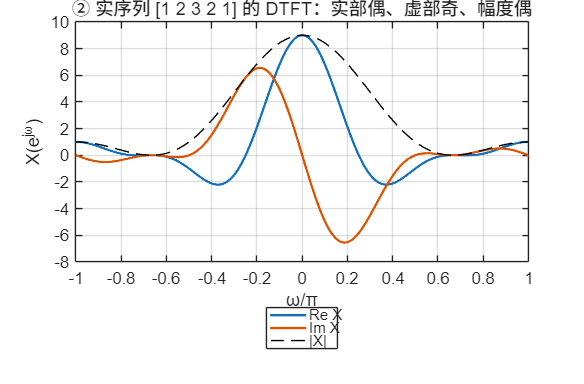

newpanel(); plot(w/pi, real(Xw), 'LineWidth', 1.4); hold on; plot(w/pi, imag(Xw), 'LineWidth', 1.4); plot(w/pi, abs(Xw), 'k--');
grid on; xlim([-1 1]);
title('② 实序列 [1 2 3 2 1] 的 DTFT：实部偶、虚部奇、幅度偶'); xlabel('ω/π'); ylabel('X(e^{jω})');
legend('Re X','Im X','|X|');

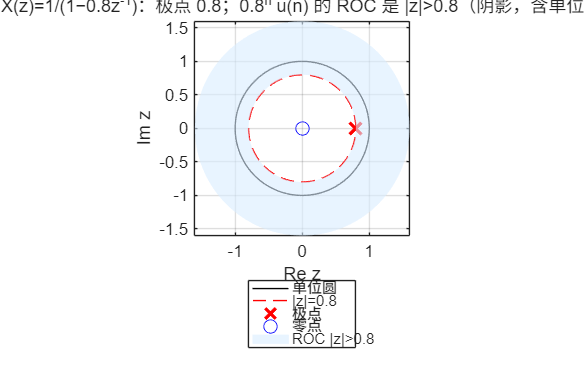

newpanel(); th = linspace(0, 2*pi, 200); plot(cos(th), sin(th), 'k'); hold on; plot(a*cos(th), a*sin(th), 'r--');
plot(a, 0, 'rx', 'MarkerSize', 10, 'LineWidth', 2); plot(0, 0, 'bo', 'MarkerSize', 8);
fill([a*cos(th) 1.6*cos(th(end:-1:1))], [a*sin(th) 1.6*sin(th(end:-1:1))], [0.85 0.93 1], 'EdgeColor', 'none', 'FaceAlpha', 0.6);
axis equal; xlim([-1.6 1.6]); ylim([-1.6 1.6]); grid on;
title('③ X(z)=1/(1−0.8z^{-1})：极点 0.8；0.8^n u(n) 的 ROC 是 |z|>0.8（阴影，含单位圆）'); xlabel('Re z'); ylabel('Im z');
legend('单位圆','|z|=0.8','极点','零点','ROC |z|>0.8');

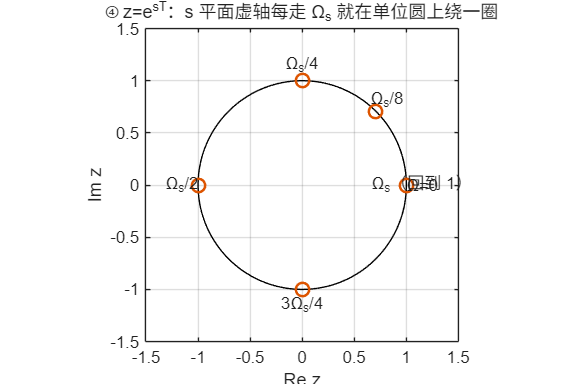

newpanel(); plot(cos(th), sin(th), 'k'); hold on; plot(real(zmap), imag(zmap), 'o', 'MarkerSize', 8, 'LineWidth', 1.5);
text(real(zmap)*1.15, imag(zmap)*1.15, {'Ω=0','Ω_s/8','Ω_s/4','Ω_s/2','3Ω_s/4','Ω_s（回到 1）'}, 'HorizontalAlignment', 'center');
axis equal; xlim([-1.5 1.5]); ylim([-1.5 1.5]); grid on;
title('④ z=e^{sT}：s 平面虚轴每走 Ω_s 就在单位圆上绕一圈'); xlabel('Re z'); ylabel('Im z');

if ~LIVE, sgtitle('频率响应 → DTFT 对称性 → z 变换与 ROC → 三种变换的关系'); end
if ~LIVE, prepare_export(f1); end
if ~LIVE, exportgraphics(f1, fullfile(outdir, '03-frequency-domain.png'), 'Resolution', 150); end

## 教师核验

assert(max(abs(ampOut - ampFormula)) < 1e-10, '实测输出幅度与 |H| 不符');
assert(ampFormula(2) < 1e-12, 'ω=0.4π 应是 5 点平均的零点');
assert(max(abs(abs(H(w)) - abs(H(w + 2*pi)))) < 1e-12, '|H| 应以 2π 为周期');
assert(symMag < 1e-12 && symRe < 1e-12 && symIm < 1e-12 && symPhase < 1e-9, '实序列对称性不符');
assert(errROC < 1e-3, '右边序列 DTFT 与 X(z)|z=e^{jω} 不符');
assert(partialX2(end) > 100, '左边序列的 Σ|x| 应发散（这里取到 n=−40 已超过 100）');
assert(abs(zmap(end) - 1) < 1e-12 && abs(zmap(4) + 1) < 1e-12, 'Ω_s 应映到 z=1，Ω_s/2 映到 z=−1');
metrics = struct('matlab_version', version, 'run_at', char(datetime('now','Format','yyyy-MM-dd HH:mm:ss')), ...
    'moving_average_taps', M, 'test_omega_over_pi', wTest/pi, 'measured_output_amplitude', ampOut, 'formula_amplitude', ampFormula, ...
    'x', x, 'symmetry_mag_err', symMag, 'symmetry_re_err', symRe, 'symmetry_im_err', symIm, 'symmetry_phase_err', symPhase, ...
    'pole', a, 'right_sided_dtft_vs_Xz_err', errROC, 'left_sided_partial_abs_sum', partialX2(end), ...
    'T', T, 'Omega_s', Ws, 'z_of_Omega_s_real', real(zmap(end)), 'z_of_Omega_s_imag', imag(zmap(end)), 'all_checks_passed', true);   % jsonencode 不支持复数
fid = fopen(fullfile(outdir, 'verification-frequency.json'), 'w', 'n', 'UTF-8'); assert(fid >= 0);
fprintf(fid, '%s\n', jsonencode(metrics, PrettyPrint=true)); fclose(fid);
disp(metrics); fprintf('\n课堂图已保存到：%s\n', outdir);

                matlab_version: '25.2.0.3360999 (R2025b) Update 7'
                        run_at: '2026-09-18 19:30:06'
           moving_average_taps: 5
            test_omega_over_pi: [0.2000 0.4000 0.8000]
     measured_output_amplitude: [0.6472 3.7345e-15 1.0772e-15]
             formula_amplitude: [0.6472 5.5511e-17 6.2063e-17]
                             x: [1 2 3 2 1]
              symmetry_mag_err: 0
               symmetry_re_err: 0
               symmetry_im_err: 0
            symmetry_phase_err: 0
                          pole: 0.8000
    right_sided_dtft_vs_Xz_err: 5.3169e-04
    left_sided_partial_abs_sum: 3.7611e+04
                             T: 0.0100
                       Omega_s: 628.3185
             z_of_Omega_s_real: 1
             z_of_Omega_s_imag: -2.4493e-16
             all_checks_passed: 1


课堂图已保存到：C:\Users\Administrator\AppData\Local\Temp\Editor_lhbfa\results



function prepare_export(fig)
axesList = findall(fig, 'Type', 'axes');
for a = 1:numel(axesList), axesList(a).Toolbar.Visible = 'off'; end
drawnow;
end